clear
% Loading data
nodepos = load('kiind_fileok\Np.mat').Np;
shearrates = load('kiind_fileok\Shearrate.mat').SRnode;
shearrates(shearrates(:, :) == -1e+30) = 0;
temps = load('kiind_fileok\Tnode.mat').Tnode;
fillstatus = load('kiind_fileok\Fillstatus.mat').Fillstatus;
connectednodes = load('kiind_fileok\connectedNodes.mat').connectedNodes;
connectedelements = load('kiind_fileok\connectedElements.mat').connectedElements;

% Mapping the shearrates and temperatures at the nodes to the elements
elementnodeids = connectednodes + 1; % +1 so that indexing will work
elementshearrates = getElementValues(elementnodeids, shearrates);
elementtemps = getElementValues(elementnodeids, temps);
elementnodesfilled = getElementValues(elementnodeids, fillstatus);

% Calculating shearrate and temperature differences within the elements
sheardiffs = calcElementDiffs(elementshearrates);
tempdiffs = calcElementDiffs(elementtemps);

% Calculating element fill status
elementfillstatus = calcElementFillstatus(elementnodesfilled);


% Mapping the coordinates of the centorids of the elements to the elements
elementcoordinates = zeros(size(elementnodeids, 1), 3);
for i = 1:size(elementnodeids, 1)
    columnids = elementnodeids(i, :);
    x = mean(nodepos(columnids, 1));
    y = mean(nodepos(columnids, 2));
    z = mean(nodepos(columnids, 3));
    elementcoordinates(i, :) = [x, y, z];
end
%elementcoordinates

% Plotting the shear rate differences to the elements on a 3d scatter plot
timestep =15

timestep = 15

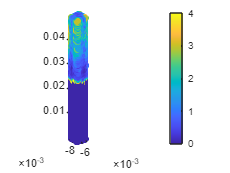

plotElementData(elementcoordinates, sheardiffs, timestep, 'no')

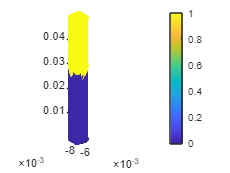

plotElementData(elementcoordinates, elementfillstatus, timestep, 'yes')

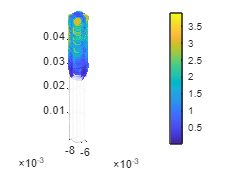

plotFillElementData(elementcoordinates, elementfillstatus, sheardiffs, timestep, 'no')

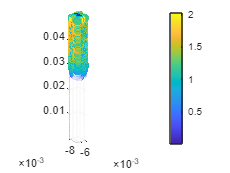

plotFillElementData(elementcoordinates, elementfillstatus, tempdiffs, timestep, 'no')

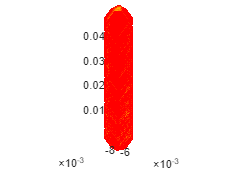

[highsheardiffs, normalsheardiffs, highsheardiffsbytimestep] = calcHighDiffElements(elementfillstatus, sheardiffs, 2);

x = elementcoordinates(:, 1);
y = elementcoordinates(:, 2);
z = elementcoordinates(:, 3);

scatter3(x(highsheardiffs(:, 1)), y(highsheardiffs(:, 1)), z(highsheardiffs(:, 1)), 100, "filled", "d", "red")
hold on
scatter3(x(normalsheardiffs), y(normalsheardiffs), z(normalsheardiffs), 100,  "filled", "d","y", 'MarkerFaceAlpha', 0.1,'MarkerEdgeAlpha', 0.2)
axis equal
hold off

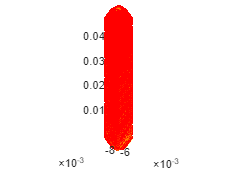


[hightempdiffs, normaltempdiffs, hightempdiffsbytimestep] = calcHighDiffElements(elementfillstatus, tempdiffs, 2);

x = elementcoordinates(:, 1);
y = elementcoordinates(:, 2);
z = elementcoordinates(:, 3);

scatter3(x(hightempdiffs(:, 1)), y(hightempdiffs(:, 1)), z(hightempdiffs(:, 1)), 100, "filled", "d", "red")
hold on
scatter3(x(normaltempdiffs), y(normaltempdiffs), z(normaltempdiffs), 100,  "filled", "d","y", 'MarkerFaceAlpha', 0.1,'MarkerEdgeAlpha', 0.2)
axis equal
hold off

tic
[newnodepos_shearrate, newnodeconnections_shearrate] = createNewMeshOneNode(highsheardiffs, shearrates, elementnodeids, nodepos);
toc

Elapsed time is 0.488985 seconds.



tic
[newnodepositions_shearrate, newelementnodeids_shearrate] = createNewMeshMultiNode(highsheardiffs, elementnodeids, nodepos);
toc

Elapsed time is 19.051791 seconds.


function elementvalues = getElementValues(elementnodeids, values) % Function for mapping node values to elements
    elementvalues = zeros(size(elementnodeids, 1), size(elementnodeids, 2), size(values, 1));
    for i = 1:size(elementnodeids, 1)
        columnids = elementnodeids(i, :);
        currentvalues = values(:, columnids);
        elementvalues(i, :, :) = currentvalues';
    end
end


% Function for calculating de diffs in the elements
function elementdiffs = calcElementDiffs(elementvalues)
    elementdiffs = (max(elementvalues, [], 2) - min(elementvalues, [], 2)) ./ abs(mean(elementvalues, 2));%table2array(rowfun(@(x) max(x) - min(x), table(elementvalues)));
    elementdiffs = reshape(elementdiffs, size(elementdiffs, 1), size(elementdiffs, 3));
    elementdiffs(isnan(elementdiffs)) = 0;
end


% Function for calculating the fillstatus in the elements possible node
% values of 3 and 4 are ignored because they are not present in the data
% and will likely not be used anyways
function elementfillstatus = calcElementFillstatus(elementvalues)
    elementfillstatus = zeros(size(elementvalues, 1), size(elementvalues, 3));
    for i = 1:size(elementvalues, 1)
        for j = 1:size(elementvalues, 3)
            if all(elementvalues(i, :, j) == 0)
                elementfillstatus(i, j) = 1;
            else
                elementfillstatus(i, j) = 0;
            end
        end
    end
end


% Function for separating the indices of filled and empty elements for
% every timestep
function [filledelements, emptyelements] = getFilledElements(elementfillstatus)
    filledelements = cell(1, size(elementfillstatus, 2));
    emptyelements = cell(1, size(elementfillstatus, 2));
    
    for i = 1:size(elementfillstatus, 2)
        filledindices = find(elementfillstatus(:, i) >= 1);
        emptyindices = find(elementfillstatus(:, i) < 1);
        filledelements{i} = filledindices;
        emptyelements{i} = emptyindices;
    end
end


% Function for retrieving elements with high diff values, the normal
% elements and a cell containing the highdiff elements by timestep - this
% might be removed if there is no need for use
function [highdiffelements, normalelements, highdiffsbytimestep] = calcHighDiffElements(elementfillstatus, results, thresholdfactor)
    [filledelements, emptyelements] = getFilledElements(elementfillstatus);

    highdiffelements = [];
    highdiffsbytimestep = cell(1, size(results, 2));

    for i = 1:size(results,2)
        threshold = thresholdfactor * mean(nonzeros(results(filledelements{i}, i)));
        highdiffs = find(results(filledelements{i}, i) > threshold);
        newelements = highdiffs(~ismember(highdiffs, highdiffelements));
        timestepatregister = zeros(size(newelements)) + i;
        newelements = [newelements, timestepatregister];
        highdiffelements = [highdiffelements; newelements];
        highdiffsbytimestep{i} = highdiffs;
    end
    allelementids = 1:size(results, 1);
    normalelements = allelementids(~ismember(allelementids, highdiffelements(:, 1)));
end


% Function for creating a new mesh by adding new nodes to the middle points
% of the edges of the elements
function [newnodepos, newelementnodeids] = createNewMeshMultiNode(highdiffelements, elementnodeids, nodepos)
    % Create matrix mapping edges to elements
    edges = nchoosek(1:size(elementnodeids, 2), 2);
    edges = transpose(edges);
    edges = reshape(edges, [1, 12]);
    elementedges = elementnodeids(:, edges);
    elementedges = reshape(transpose(elementedges),  2, 6, []);
    elementedges = permute(elementedges, [2, 1, 3]);
    % Choose the edges to refine based on elements chosen for refinement
    edgestorefine = elementedges(:, :, highdiffelements(:, 1));
    edgestorefine = permute(edgestorefine, [2, 1, 3]);
    edgestorefine = transpose(reshape(edgestorefine, 2, []));
    % Remove duplicate rows
    edgestorefine_orig = edgestorefine;
    edgestorefine = unique(sort(edgestorefine, 2), 'rows', 'stable'); % sorting edgestorefine so that edges like 1-2 and 2-1 will be treated as one
    % Get coordinates of the nodes of the edges
    X = nodepos(:, 1);
    Y = nodepos(:, 2);
    Z = nodepos(:, 3);
    refine_X = X(edgestorefine);
    refine_Y = Y(edgestorefine);
    refine_Z = Z(edgestorefine);
    % Calculate the coordinates of the new nodes
    new_X = mean(refine_X, 2);
    new_Y = mean(refine_Y, 2);
    new_Z = mean(refine_Z, 2);
    newnodes = [new_X, new_Y, new_Z];
    newnodeids = transpose(size(nodepos, 1)+1:size(nodepos, 1)+size(newnodes, 1));
    % Affected elements -> their edges (sorted) -> newly created nodes ->
    % delaunay-triang.
    elementedges_linear = sort(transpose(reshape(permute(elementedges, [2, 1, 3]), 2, [])), 2);
    affectedelements = unique(ceil(find(ismember(elementedges_linear, edgestorefine, 'rows')) / size(elementedges, 1)));
    
    % Reconnect the vertices and the new points in all affected elements with
    % delaunay-triangulation
    newconnectivity = cell(size(affectedelements, 1), 1);
    for i=1:size(affectedelements, 1)
        % Get hold of the edges and nodes of the current element
        elementedges_current = sort(elementedges(:, :, affectedelements(i)), 2);
        elementnodes_current = unique(reshape(elementedges_current, [], 1));
        elementpoints_current = nodepos(elementnodes_current ,:);
        % Get hold of the respective new nodes to the current element
        newnodeindices_current = find(ismember(edgestorefine, elementedges_current, 'rows'));
        newpoints_current = newnodes(newnodeindices_current, :);
        newnodes_current = newnodeids(newnodeindices_current, :);
        allpoints_current = [elementpoints_current; newpoints_current];
        allnodes_current = [elementnodes_current; newnodes_current];
        DT = delaunayn(allpoints_current);
        %DT_ = delaunay(allpoints_current);
        newconnectivity_current = allnodes_current(DT);
        newconnectivity(i) = {newconnectivity_current};
    end

    % Creating the new connectivity matrix
    newconnectivity = cell2mat(newconnectivity);
    newelementnodeids = elementnodeids;
    % Removing refined elements
    newelementnodeids(affectedelements, :) = [];
    % Adding new elements
    newelementnodeids = [newelementnodeids; newconnectivity];
    % Adding new node positions
    newnodepos = [nodepos; newnodes];
end


% Function for calculating the positions of new nodes in each
% highdiffelement
function [newnodes, newnodeids] = calcNewNodePos(highdiffelements, values, elementnodeids, nodepos)
    newnodes = [];
    newnodeids = [];
    nodeid = max(elementnodeids, [], "all");
    for i=1:size(highdiffelements, 1)
        nodeid = nodeid + 1;
        elementnodes = elementnodeids(highdiffelements(i, 1), :);
        elementnodecoords = nodepos(elementnodes, :);
        elementvalues = values(highdiffelements(i, 2), elementnodes(:));
        edges = nchoosek(1:length(elementvalues), 2);
        edges_t = transpose(edges);
        pair_values = elementvalues(edges);
        relativeedgediffs = abs(diff(pair_values, 1, 2)) / sum(abs(diff(pair_values, 1, 2)));
        edgecoords = elementnodecoords(edges_t(:, :), :);
        edgecenters = transpose([mean(reshape(edgecoords(:, 1), 2, []), 1); mean(reshape(edgecoords(:, 2), 2, []), 1); mean(reshape(edgecoords(:, 3), 2, []), 1)]);
        centroid = [mean(elementnodecoords(:, 1)), mean(elementnodecoords(:, 2)), mean(elementnodecoords(:, 3))];
        vectors = edgecenters - centroid;
        sumvector = sum(vectors .* relativeedgediffs, 1);
        newnodepos = centroid + sumvector;
        newnodes = [newnodes; newnodepos];
        newnodeids = [newnodeids;[elementnodes, nodeid]];
    end
end


% Function for creating the new node connections
function newnodeconnections = createNewNodeConnections(newnodeids)
    newnodeconnections = [];
    for i=1:size(newnodeids, 1)
        selections = nchoosek(1:length(newnodeids(i, 1:end-1)), size(newnodeids, 2)-2);
        selections = [selections, (zeros(size(selections, 1), 1) + max(selections, [], "all")+1)];
        newconnectivity = reshape(newnodeids(i, selections), size(selections));
        newnodeconnections = [newnodeconnections; newconnectivity];
    end
end


% Function for creating the entire new mesh with node positions and
% connectivity
function [newnodepos, newelementnodeids] = createNewMeshOneNode(highdiffelements, values, elementnodeids, nodepos)
    [newnodes, newnodeids] = calcNewNodePos(highdiffelements, values, elementnodeids, nodepos);
    newnodeconnections = createNewNodeConnections(newnodeids);
    % Creating complete new connectivity matrix
    newelementnodeids = elementnodeids;
    newelementnodeids(highdiffelements(1, :), :) = [];
    newelementnodeids = [newelementnodeids; newnodeconnections];
    % Appending new node positions to old ones
    newnodepos = [nodepos; newnodes];
end


% Below here are functions for handy data visualization
% Function for plotting results
function plotElementData(elementcoordinates, results, timestep, colorlimit)
    x = elementcoordinates(:, 1);
    y = elementcoordinates(:, 2);
    z = elementcoordinates(:, 3);

    scatter3(x, y, z, 20, results(:, timestep), "filled")
    axis equal
    if strcmp(colorlimit, 'yes')
        clim([min(results(:)), max(results(:))])
    end
    colorbar
end


% Function for plotting the filling method while also displaying the 
% element values for a feature in the filled region. The flowfront is
% considered as empty so element values in the flowfront are ignored
function plotFillElementData(elementcoordinates, elementfillstatus, results, timestep, colorlimit)
    [filledelements, emptyelements] = getFilledElements(elementfillstatus);

    x = elementcoordinates(:, 1);
    y = elementcoordinates(:, 2);
    z = elementcoordinates(:, 3);

    scatter3(x(filledelements{timestep}), y(filledelements{timestep}), z(filledelements{timestep}), 20, results(filledelements{timestep}, timestep), "filled", 'MarkerEdgeColor', 'none')
    if strcmp(colorlimit, 'yes')
        clim([min(results(:)), max(results(:))])
    end
    colorbar
    hold on
    scatter3(x(emptyelements{timestep}), y(emptyelements{timestep}), z(emptyelements{timestep}), 20, 'filled', 'w', 'MarkerFaceAlpha', 0.2,'MarkerEdgeAlpha', 0.2)
    axis equal
    hold off
end
